# **SISTEMAS DE CONTROL DISCRETO                                **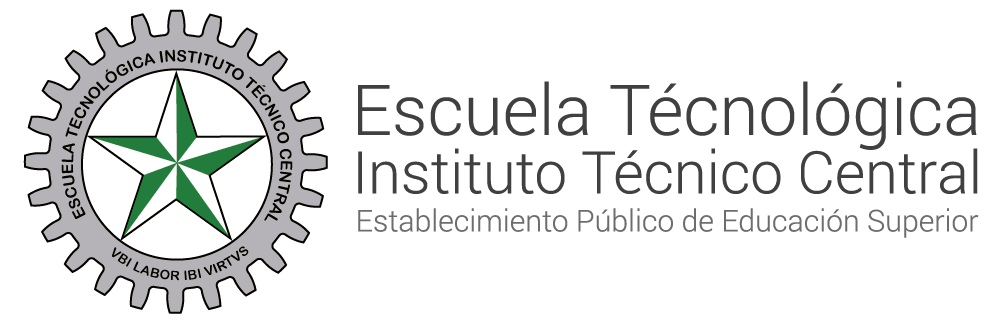

# **Solución ecuaciones diferenciales **

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

#### OBJETIVO

Comprender y aplicar el concepto de representación de sistemas mediante la transformada Z, así como la **solución de ecuaciones en diferencias**, para analizar y diseñar sistemas de control en el dominio discreto.

#### Ejercicio

Encontrar la transformada Z y resolver con respecto a la variable de salida $y\left(k\right)$


$$y\left\lbrack k+2\right\rbrack +0\ldotp 5y\left\lbrack k+1\right\rbrack +0\ldotp 2y\left\lbrack k\right\rbrack =u\left\lbrack k\right\rbrack$$


Asuma condiciones iniciales iguales a cero (0)

## SOLUCIÓN

#### PASO 1 Transformar la ecuación en diferencias al dominio de z mediante la transformada Z.

recordando que por definición, la transformada de Z esta dada por:

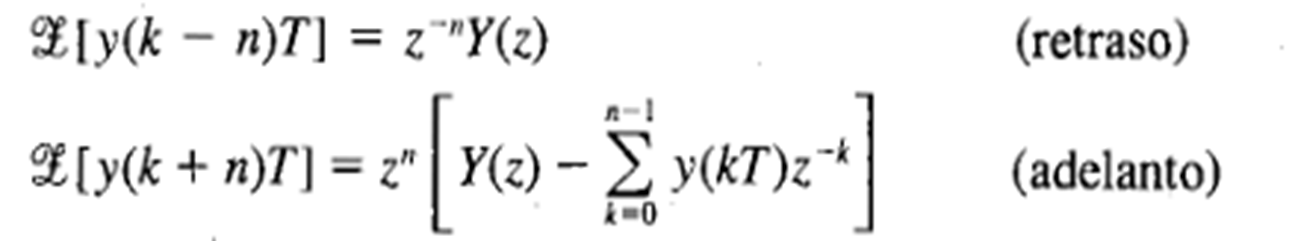

Se obtiene


$$z^2 Y\left\lbrack z\right\rbrack +0\ldotp 5zY\left\lbrack z\right\rbrack +0\ldotp 2Y\left\lbrack z\right\rbrack =\frac{z}{z-1}$$


#### PASO 2 Manipular las ecuaciones algebraicas transformadas y resolverlas para la variable de salida

Factorizando los términos de $Y\left(z\right)$ se obtiene la siguiente expresión:


$$Y\left\lbrack z\right\rbrack \left\lbrace z^2 +0\ldotp 5z+0\ldotp 2\right\rbrace =\frac{z}{z-1}$$


Dado que lo que nos interesa es obtener el comportamiento de $y\left\lbrack k\right\rbrack$ en el dominio del tiempo discreto, procedemos a despejar la función en términos de $Y\left\lbrack z\right\rbrack$ 


$$Y\left\lbrack z\right\rbrack =\frac{z}{\left(z-1\right)\left(z^2 +0\ldotp 5z+0\ldotp 2\right)}$$


#### PASO 3 Realizar la expansión en fracciones parciales de la ecuación algebraica transformada.

A continuación vamos a representar la función utilizando matlab:

syms z
numerator = [1 0];
a_0=[1 -1];
a_1=[1 0.5 0.2];
denominator = conv(a_0,a_1);
ts=1;
Y_z = tf(numerator,denominator)


Y_z =
 
               s
  ---------------------------
  s^3 - 0.5 s^2 - 0.3 s - 0.2
 
Continuous-time transfer function.
Model Properties


Ahora procedemos a utilizar la función "residue" con el objetivo de obtener la descomposición en fracciones parciales de la función de transferencia:

[r,p,k] = residue(numerator,denominator)

r =    0.5882 + 0.0000i
  -0.2941 - 0.3569i
  -0.2941 + 0.3569i


p =    1.0000 + 0.0000i
  -0.2500 + 0.3708i
  -0.2500 - 0.3708i



k =

     []



La documentación de matlab nos dice que la fracción parcial se puede reescribir de la siguiente manera:

Y_z_fract=simplify((r(1)/(1-(p(1)*z^(-1)))))+simplify((r(2)/(1-(p(2)*z^(-1)))))+simplify((r(3)/(1-(p(3)*z^(-1)))))

$$Y\_z\_fract = \frac{10\,z}{17\,\left(z-1\right)}+\frac{20\,z\,\left(-\frac{5}{17}+\frac{9\,\sqrt{55}\,\mathrm{i}}{187}\right)}{20\,z+5+\sqrt{55}\,\mathrm{i}}-\frac{20\,z\,\left(\frac{5}{17}+\frac{9\,\sqrt{55}\,\mathrm{i}}{187}\right)}{20\,z+5-\sqrt{55}\,\mathrm{i}}$$

#### PASO 4

A continuación obtendremos la transformada inversa Z

### 
$$Y\left\lbrack z\right\rbrack =\frac{0\ldotp 588z}{z-1}-\frac{1\ldotp 036e^{\textrm{j1}\ldotp 283} z}{z+0\ldotp 25+\textrm{j0}\ldotp 370}-\frac{1\ldotp 036e^{-\textrm{j1}\ldotp 283} z}{z+0\ldotp 25-\textrm{j0}\ldotp 370}$$


syms k;
simplify(iztrans(Y_z_fract,z,k))

$$ans = \frac{10}{17}-\frac{5\,{\left(-\frac{1}{4}+\frac{\sqrt{55}\,\mathrm{i}}{20}\right)}^{k}}{17}-\frac{5\,{\left(-\frac{1}{4}-\frac{\sqrt{55}\,\mathrm{i}}{20}\right)}^{k}}{17}+\frac{9\,\sqrt{55}\,{\left(-\frac{1}{4}-\frac{\sqrt{55}\,\mathrm{i}}{20}\right)}^{k}\,\mathrm{i}}{187}-\frac{9\,\sqrt{55}\,{\left(-\frac{1}{4}+\frac{\sqrt{55}\,\mathrm{i}}{20}\right)}^{k}\,\mathrm{i}}{187}$$

#### Taller

- Encuentre y grafique la siguiente transformada z

### 
$$x\left(k\right)=\frac{1}{a}\left(1-e^{-{\textrm{aT}}_s } \right)$$


- Obtenga la transformada x de la siguiente señal

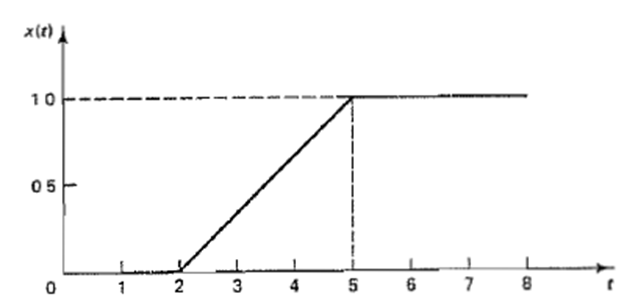

-     Obtenga las tranformadas inversas Z de

- Resuelva la siguiente ecuación en diferencias


$$x\left\lbrack k+2\right\rbrack -x\left\lbrack k+1\right\rbrack +0\ldotp 1x\left\lbrack k\right\rbrack =u\left\lbrack k\right\rbrack$$


- Resuelva la siguiente ecuación en diferencias y grafique

$x\left\lbrack k+2\right\rbrack -x\left\lbrack k\right\rbrack =0$ con condiciones iniciales $x\left\lbrack k=0\right\rbrack =1\;$y $x\left\lbrack k=1\right\rbrack =0$